# Data Input and Output

The following will use the files: (obviously** you should change the file directory and name if you are not running it on Tom K's machine**)

matfile = 'data/statepop'
txtfile = 'data/GlobalTempbyYear.txt'
csvfile = 'data/sunspotsbyyear.csv'
xlsfile = 'data/GlobalCarbonBudget2018.xlsx'

## Inputting Data

Inputting data into a program can be the most time intensive activity.

MATLAB allows you to input (load) data in several ways

**By hand** – the old fashion way

-  very time consuming

-  prone to error

**GUI** – 

- straightforward and easy, 

- hard to systematize 

- accessible in the variable area of the HOME tab

**Command line** -  

- best way for a program you plan to run multiple times

- `load, csvread, xlsread, readtable, textscan`

## `By Hand`

Please do not input large amounts of data by hand

- You'll introduce errors

- And drive yourself crazy

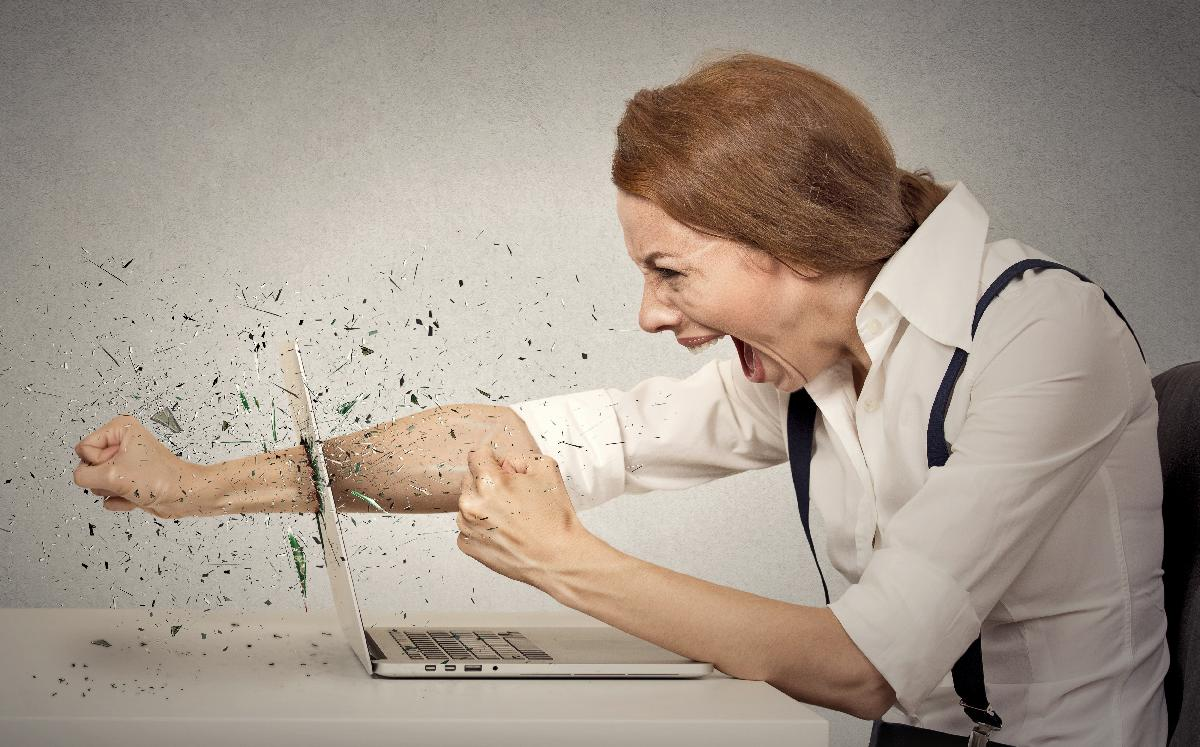

When to put input data by hand?

- If it takes less than a minute

- if your data isn't in electronic form 

## GUI

The variable area of the HOME tab allows you to

- create, edit, and save variables in your workspace

- import all or a portion of .txt, .xls, .csv, .mat, .dat files

- see and name columns of data in file

`uiimport` - command brings up the import GUI

## Command Line Commands

`load` – loads numeric variables into MATLAB

`csvread` – loads numeric values from a .csv file 

`xlsread` – loads texts and numeric values from .xls, .xlsx, .xlsm, .xltx, and .xltm files 

`readtable` – creates a table of variables from the columns of a file

`textscan`  - reads formatted text into a cell array 

`importdata` – loads data (including images) from a file, can specify delimiter and column headings 

## `LOAD`

- works for many file types, (but usually only ascii files,** really I would only use this for .mat files**)

- otherwise data should be numeric – is imported as doubles

load(matfile)

## `IMPORTDATA`

- most general of the functions (can import images)

- can specify delimiter (`delimiterIn`) and header lines (`headerlinesIn`)

- can output MATLAB's best guess at column delimiter (`delimiterOut`) and number of header lines (`headerlinesOut`)

Example setting `' '` (space) as a delimiter (what separates values). importdata reads .csv files well enough.

txtimport = importdata(txtfile,'') 
csvimport = importdata(csvfile)

## `CSVREAD`

- works for .csv files containing strictly numeric values

- stores all values in large matrix M

- can start at arbitrary column and row, *R1 C1 …*

Example using .csv file 

csv = csvread(csvfile)

## `XLSREAD`

- reads all numeric data into the matrix X 

- can specify excel sheet and range

- can include output variables to capture text

Example using a quite complicated .xlsx file

Xlsx = xlsread(xlsfile, 'Global Carbon Budget','A23:F78')
[num,text,raw] = xlsread(xlsfile, 'Global Carbon Budget','A20:F79')

The advanced option for reading data from an xlsx file may be to capture the headers as well. You can do this with the following

rawT = cell2table(raw(2:end,:))
match = [" " , "-"];
newraw = erase(raw(1,:),match);
% spaces are no good in table header names
rawT.Properties.VariableNames = newraw

## `READTABLE`

- creates a table from column data in a file

- `T` contains one variable per column in data file

Ttxt = readtable(txtfile)
Tcsv = readtable(csvfile)
Txls = readtable(xlsfile)

## `TEXTSCAN`

- reads formatted data from a file or string (must use `fopen``() `and `fclose``()`)

- stores any type of data in cell array *C*

- must specify the exact format in <`formatSpec`> using *conversion specifiers*

- this function is also good at filtering through character and string arrays based on conversion specifiers

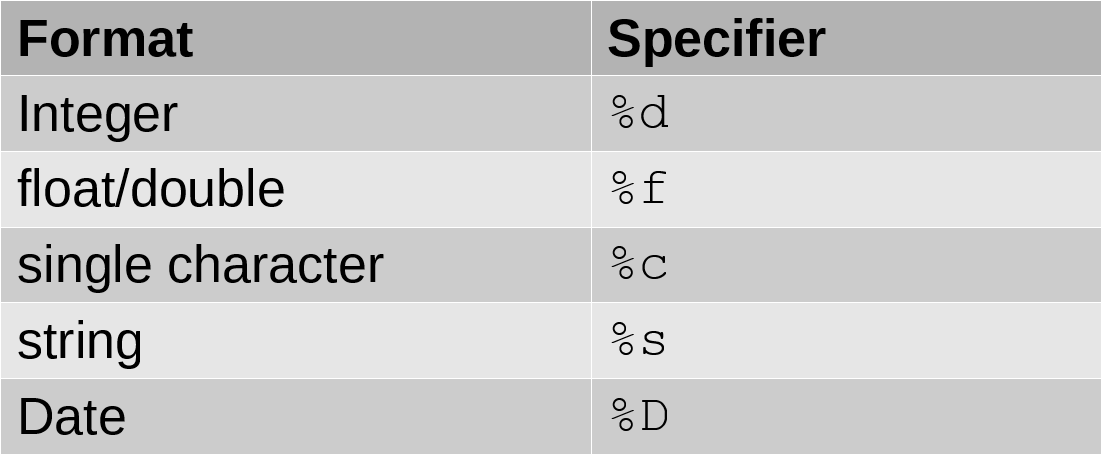

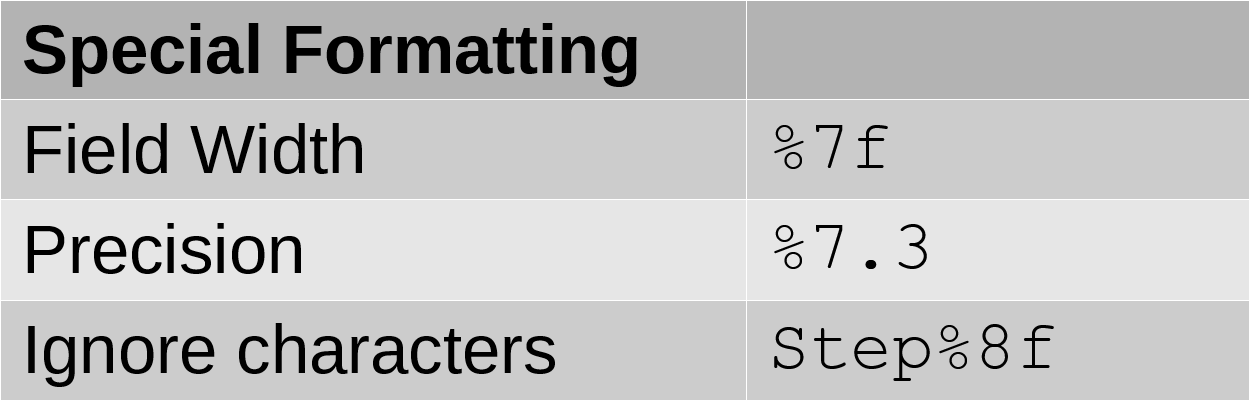

fid = fopen(txtfile)
N = 171;
scantxt = textscan(fid,'%f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f',N)
fclose(fid);

## Outputting Data

Saving your processed variables is a good idea

Save your workspace (.mat files)

Output the data into a file with commands

- `dlmwrite`

- `csvwrite`

- `xlswrite`

- `writetable`

## `DLMWRITE`

- writes the data array *M* to `<filename> `(any ascii file)

- adds to an existing file with `'-append'`

- specify delimiter or row/column offsets with `Name,Value`pairs or further arguments

## `CSVWRITE`

- writes data array *M *to a *.csv*file

- specify starting row and column of the *.csv*file with <row> and <col>

- *M *must be numeric

- *.csv *file carries only 5 digits of precision   

## `XLSWRITE`

- writes data array *A *to an excel spreadsheet

- *A *can be any type of array

- specify specific sheets and cell ranges to write data to the spreadsheet

## `WRITETABLE`

- writes table *T* to <filename> OR *T.txt*

- each column of each variable in *T *becomes a column in the output file

- variable names of *T* become column headings in the first line of the file